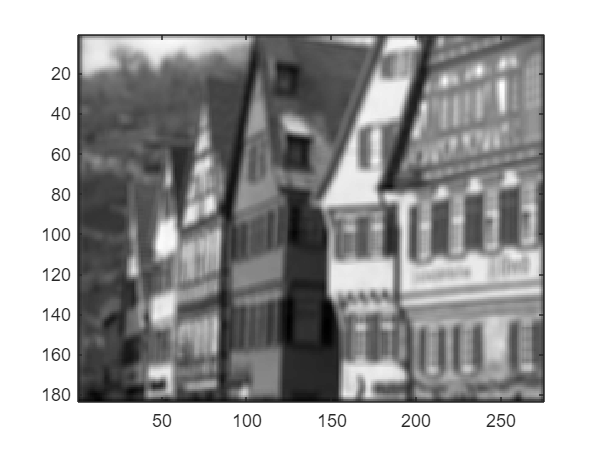

old = imread(['D:\Practical\Matlab_ws\Robot Vision [06-25024] Summative_1\Part 2\','Old_house.jpg']);
fsize = 5;
sig1 = 2;
n = fsize;
gf = zeros(fsize,fsize);
for i = 1:fsize
    for j = 1:fsize
        gf(i,j) = 1/(2*pi*sig1*sig1) * exp(-((i-(n+1)/2)^2+(j-(n+1)/2)^2)/(2*sig1^2));
    end
end

old = im2gray(old);
[red]= convolve(gf,old);
im = red;
im = uint8(im);
show_image(im)

%title('Question 1')

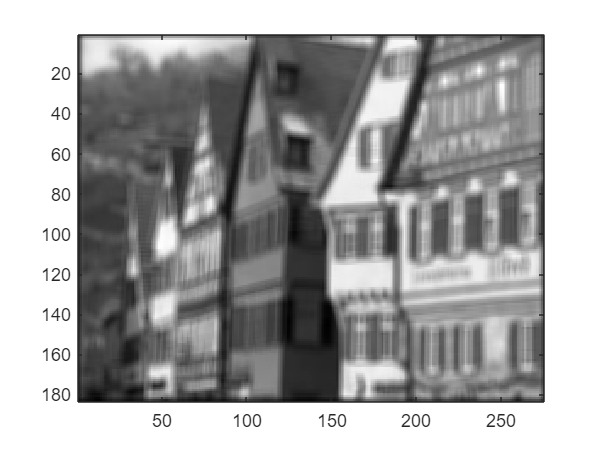

mfsize = 5;
mf = ones(mfsize,mfsize);
mf = mf/(mfsize*mfsize);
[red1]= convolve(mf,old);
im1 = red1;
im1 = uint8(im1);
show_image(im1)

%title('Question 2')

mdsize = 5;
medf = ones(mdsize,mdsize);
[red2]= simplemedian(medf,old);
im2 = red2;
im2 = uint8(im2);
size(im2)

ans =    183   275


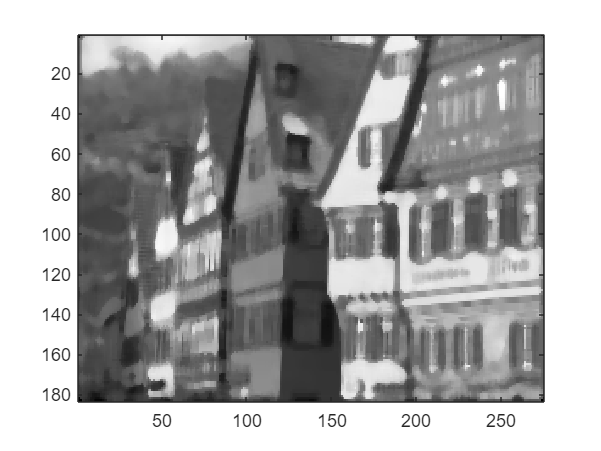

show_image(im2)

%title('Question 3')

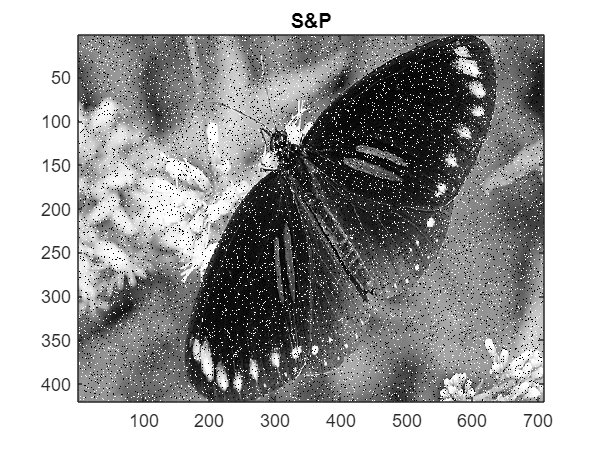

butfly = imread(['D:\Practical\Matlab_ws\Robot Vision [06-25024] Summative_1\Part 2\','Butterfly.jpg']);
fsize=5;
msize =5;
mdsize =5;
butfly= rgb2gray(butfly);
bfsp = imnoise(butfly,'salt & pepper',.09);
show_image(bfsp)
title('S&P')

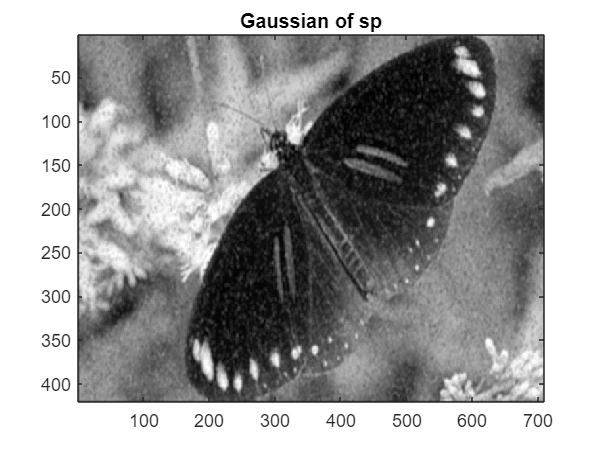

%gaussian of sp
igsp = convolve(gf,bfsp);
igsp = uint8(igsp);
show_image(igsp)
title('Gaussian of sp')

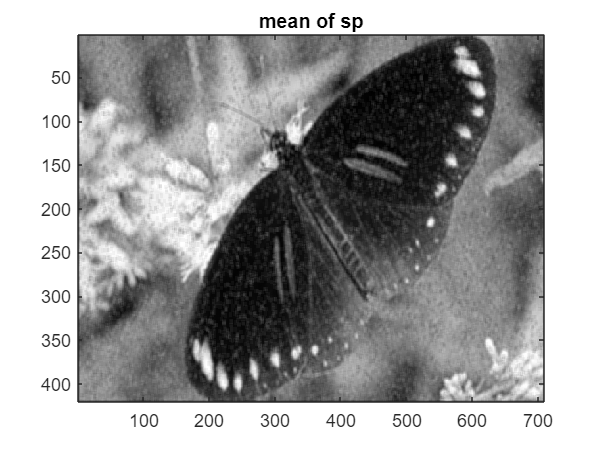

%mean of sp
immfsp = convolve(mf,bfsp);
immfsp = uint8(immfsp);
show_image(immfsp)
title('mean of sp')

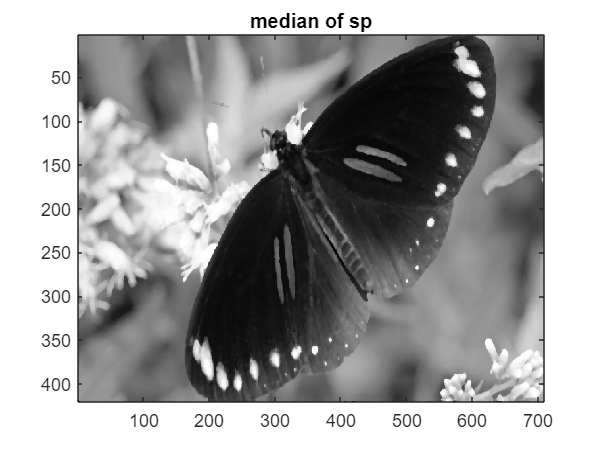

%median of sp
immdsp = simplemedian(medf,bfsp);
immdsp = uint8(immdsp);
show_image(immdsp)
title('median of sp')

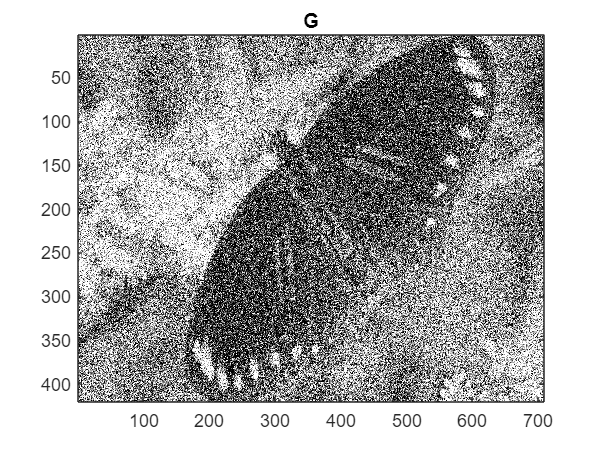


bfg = imnoise(butfly,'gaussian',0.1,0.2);
show_image(bfg)
title('G')

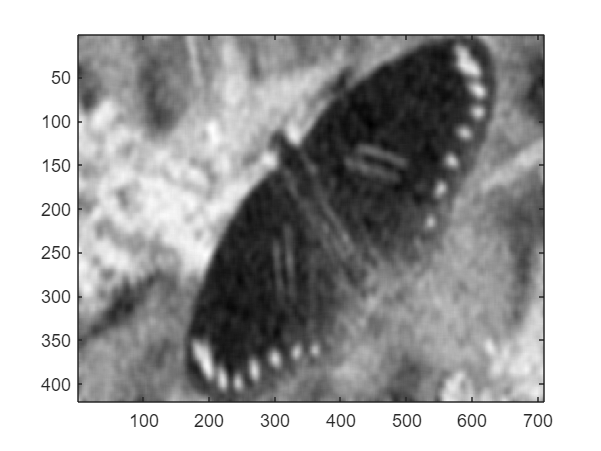

%gaussian of g
igg =  convolve(gf,bfg);
igg = uint8(igg);
igg1 = imgaussfilt(bfg,5,FilterSize=15);
show_image(igg1)

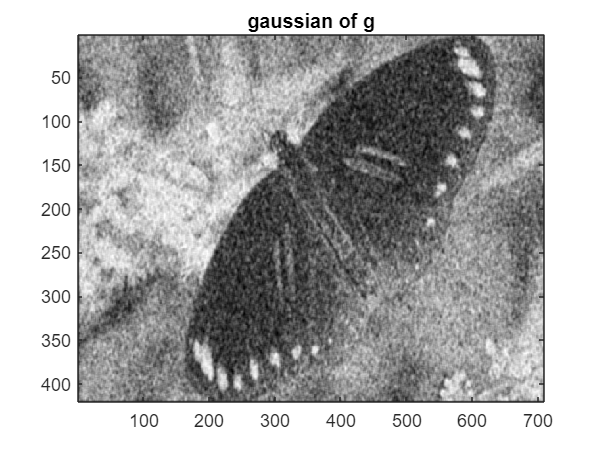

show_image(igg)
title('gaussian of g')

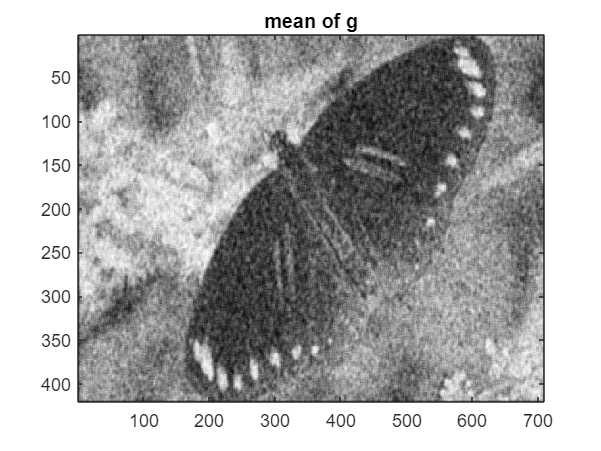

%mean of g
immfg = convolve(mf,bfg);
immfg = uint8(immfg);
show_image(immfg)
title('mean of g')

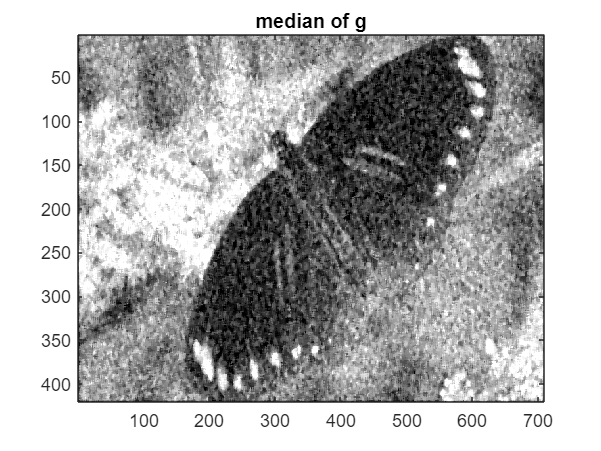

%median of g
immdg = simplemedian(medf,bfg);
immdg = uint8(immdg);
show_image(immdg);
title('median of g')

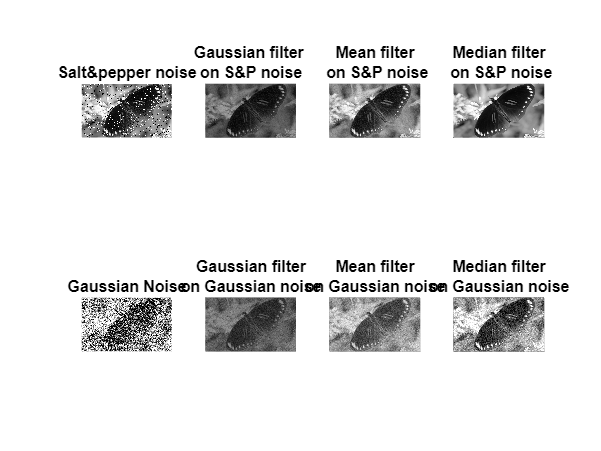


subplot(2,4,1);
imshow(bfsp);
title('Salt&pepper noise')
subplot(2,4,2);
imshow(igsp);
title({'Gaussian filter ','on S&P noise'})
subplot(2,4,3);
imshow(immfsp);
title({'Mean filter',' on S&P noise'})
subplot(2,4,4);
imshow(immdsp);
title({'Median filter',' on S&P noise'})
subplot(2,4,5);
imshow(bfg);
title('Gaussian Noise')
subplot(2,4,6);
imshow(igg);
title({'Gaussian filter','on Gaussian noise'})
subplot(2,4,7);
imshow(immfg);
title({'Mean filter','on Gaussian noise'})
subplot(2,4,8);
imshow(immdg);
title({'Median filter','on Gaussian noise'})

function [red] = simplemedian(f,I)

    %get the size of images
    [x, y] = size(I);
    %get the filter sizes
    [x2,y2] = size(f);

    %from filter size get the padding no. in x and y dir
    f1 = ceil(x2/2);
    f1 = f1 - 1;
    f2 = ceil(y2/2);
    f2 = f2 - 1;

    %zero pad the 3 channels to ensure same size
    I = padarray(I,[f1,f2],0,'both');
    

    %create empty matrixes for holding the convulted values
    I2 = zeros(x,y);
    
    %loop through for convolution
    %loop through rows
    for i = 1+f1:x+f1
        %loop through columns
        for j = 1+f2:y+f2
            %convolution over red channnel
            subr = I(i-f1:i+f1,j-f2:j+f2);
            subr = double(subr);
            onedr = reshape(subr.',1,[]);
            onedr = sort(onedr);
            r = median(onedr,"all");
            I2(i-f1,j-f2) = r;

        end    
    end

    %combine the convoluted matrix to form a single image
    red = I2;
end

function red = convolve(f,I)    

    %get the size of Grayscale image
    [x, y] = size(I);
    %get the filter size
    [x2,y2] = size(f);

    %from filter size get the padding no. in x and y dir
    f1 = ceil(x2/2);
    f1 = f1 - 1;
    f2 = ceil(y2/2);
    f2 = f2 - 1;

    %zero pad the Gray scale image to ensure same size
    I = padarray(I,[f1,f2],0,'both');    

    %create empty matrixes for holding the convoluted values
    I2 = zeros(x,y);
    
    %loop through for convolution
    %loop through rows
    for i = 1+f1:x+f1
        %loop through columns
        for j = 1+f2:y+f2
            %convolution over red channnel
            subr = I(i-f1:i+f1,j-f2:j+f2);
            subr = double(subr);
            r = sum(subr.*f,"all");
            I2(i-f1,j-f2) = r;
        end    
    end

    %combine the convoluted matrix to form a single image
    red = I2;    
end